clc;clear;
%Question 7a
fprintf("Question 7a")

Question 7a

x = [-3:0.1:3]; %defines a vector x that goes from -3 to 3, and increments by 0.1 every time (-3, -2.9, ... 2.9, 3)
y = F1(x); %uses the values from x to get a y value based on the function
fprintf("Graph of x^2 - 1")

Graph of x^2 - 1

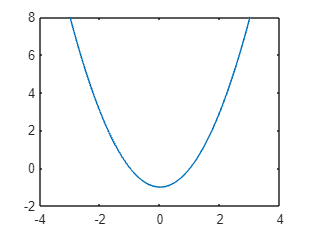

plot(x, y) %plots on the xy-plane

y = F2(x);
fprintf("Graph of e^(1-x^2)")

Graph of e^(1-x^2)

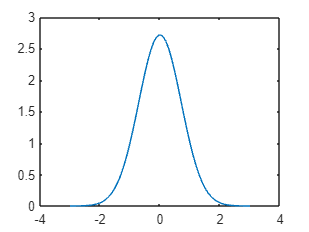

plot(x, y)


%Question 7b
fprintf("Question 7b")

Question 7b

it = iterations(3, -2, 0);
bi = bisection(-2, 0, it);
fprintf("By the bisection method, the value of x \nfor which the function x^2 - 1 = e^(1-x^2) \nholds is %.3f \n\n", bi) %using .3f, since we need 3 digits after the decimal to approximate to 10^-3

By the bisection method, the value of x 
for which the function x^2 - 1 = e^(1-x^2) 
holds is -1.251 




%Question 8
fprintf("Question 8")

Question 8

%We know 15 iterations are required based on calculations performed in
%question 4. Use a from question 4 as p0 (0.5)
fixed = fpm(15, 0.5);
fprintf("By the fixed point method, the value of x \nthat gives a root on the interval \n[0.5,1] is %.5f", fixed)

By the fixed point method, the value of x 
that gives a root on the interval 
[0.5,1] is 0.91000



%Question 9, 6d
fprintf("Question 9, 6d")

Question 9, 6d

%use midpoint as start point within the intervals. so, we will use 1.5 as
%p0 for 1<x<2, and 3.36 as p0 for e<x<4
r1 = newton(1.5);
r2 = newton(3.36);
fprintf("By Newton's method, the roots of the function \nwithin the given intervals \nare %.5f and %.5f", r1, r2)

By Newton's method, the roots of the function 
within the given intervals 
are 1.41239 and 3.05710


%Question 9, 8d
fprintf("Question 9, 8d")

Question 9, 8d

%use two bounds of intervals as p0 and p1
r1 = secant(1, 2);
r2 = secant(exp(1), 4);
fprintf("By Secant method, the roots of the function \nwithin the given intervals \nare %.5f and %.5f", r1, r2)

By Secant method, the roots of the function 
within the given intervals 
are 1.41239 and 3.05710

function result = F1(n)
    result = n.^2 - 1; %function x^2 - 1, question 7a
end
function result = F2(n)
    result = exp(1).^(1-n.^2); %function e^(1-x^2), question 7a
end
function result = F3(n)
    result = n.^2 - 1 - exp(1).^(1-n.^2); %will equal 0 when x^2 - 1 = e^(1-x^2), question 7b
end
function result = F4(n)
    result = (n-2)^2 - log(n); %Function (x-2)^2 - ln(x), question 9
end
function result = F5(n)
    result = 2*n - 4 - (1/n); %Derivative of function (x-2)^2 - lnx, question 9
end
function result = F6(n)
    result = (exp(1)^n / 3)^(1/2); %function sqrt((e^x / 3)), question 8
end
function result = iterations(sigdigs, a, b) %returns how many iterations are required to obtain the specified amount of significant digits
    k = 0;
    c = abs(b - a);
    while (c / 2.^(k+1) > (10^-sigdigs)) %This equation is the one given in the video rearranged to isolate the term containing k. Note we are using < 10^-3 rather than 5*10^-3, since this ensures absolute error less than 10^-3, like requested in the question
        k = k+1; %Increases k until more iterations won't be needed
    end
    result = k;
end
function result = bisection(a, b, it)
c = (1/2)*(a+b); %defines c
for i = 0:it %runs for number of iterations required, calculated earlier
    c = (1/2)*(a+b); %sets c for every iteration
    ck = F3(c);
    ak = F3(a);
    if(abs(ck) < 10^-6) %Terminates if F(c) ~= 0
        result = c;
        break;
    elseif(ak*ck > 0) %Moves towards b if F(a) and F(c) have same sign
        a = c;
    else %Moves towards a if F(b) and F(c) have same sign
        b = c;
    end
    result = c; %Sets return value of function
end
end
function result = newton(p0)
    result = p0;
    lastResult = p0;
    while 1
        result = result - (F4(result) / F5(result)); %performs newton's method as outlined in slides
        if(abs(F4(result)) < 10^-6) %Stop condition 1: if f(pk+1) = 0, success
            break;
        elseif(abs(result - lastResult) < 5*10^-6) %Stop condition 2: if the difference between the last result and the current result is less than 5x10^-6, then we have succesfully approximated to 10^-5. Success
            break;
        elseif(F5(result) == 0) %Stop condition 3: if f'(pk+1) = 0, failure
            fprintf("Newton's method failed");
            break;
        end
        lastResult = result;
    end
end
function result = secant(p0, p1)
    result = p1;
    lastResult = p0;
    while 1
        temp = result;
        result = result - ((F4(result)*(result-lastResult))/(F4(result) - F4(lastResult))); %Performs secant method as outliend in the slides, with result being pk and lastResult being pk-1
        lastResult = temp;
        if(abs(F4(result)) < 10^-6) %Stop condition 1, f(pk+1) = 0. Success
            break;
        elseif(abs(result - lastResult) < 5*10^-6) %Stop condition 2: if the difference between the last result and the current result is less than 5x10^-6, then we have succesfully approximated to 10^-5. Success
            break;
        elseif(F4(result) == F4(lastResult)) %Stop condition 3, f(pk+1) = f(pk). Failure
            break;
        end
    end
end
function result = fpm(iterations, p0)
    result = F6(p0);
    lastResult = p0;
    for i = 1:iterations
        if(abs(result-lastResult) < 10^-5) %breaks loop if approximated within 10^-5, like specified
            break;
        end
        lastResult = result;
        result = F6(result); %fixed point method. simple
    end
end